# Exercicio Aula

tau1 = 0;
tau2 = 1;
T0 = 1;
fo = inv(T0);
wo = 2*pi*fo;

syms n t ns

gt = exp(-t)

$$gt = {\mathrm{e}}^{-t}$$

g = @(t) exp(-t)

g = function_handle with value:
    @(t)exp(-t)



%%% Potencia do sinal
pg = 1/T0*int(gt^2,t,0,T0)

$$pg = \frac{1}{2}-\frac{{\mathrm{e}}^{-2}}{2}$$

valueP = eval(pg)

valueP = 0.4323

%%% Banda 90% da potencia
banda = valueP * 0.9

banda = 0.3891

%%% Sintese do sinal
Dn = 1/T0*int(gt*exp(-(j)*n*wo*t),t,0,T0)

$$Dn = -\frac{{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{1+2\,\pi \,n\,\mathrm{i}}$$

N = 1;
n = [-N:1:N];
a = eval(Dn)

a =    0.0156 + 0.0981i   0.6321 + 0.0000i   0.0156 - 0.0981i


figure(1)
stem(n,a);

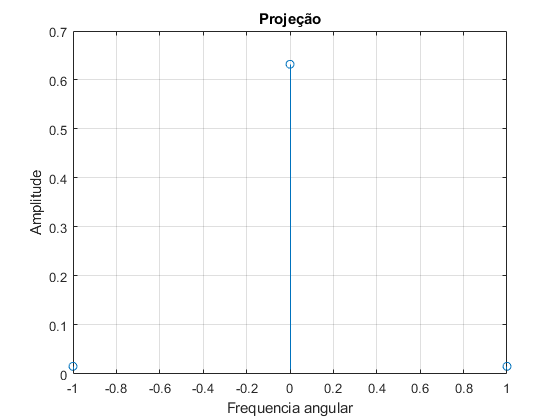

grid; 
title('Projeção');
xlabel('Frequencia angular');
ylabel('Amplitude');

## Síntese


aux = 0;
tempo = [0:0.01:T0];
yt = 0 

yt = 0

for k=1:2*N+1
    aux  =  aux + a(k)*exp(j*n(k)*wo*tempo);
    yt = yt + a(k)*exp(j*n(k)*wo*t);
end
aux

aux =     0.6634    0.6756    0.6877    0.6996    0.7112    0.7225    0.7334    0.7439    0.7540    0.7636    0.7727    0.7813    0.7892    0.7966    0.8032    0.8092    0.8145    0.8191    0.8230    0.8261    0.8284    0.8300    0.8307    0.8307    0.8299    0.8284    0.8260    0.8229    0.8190    0.8144    0.8091    0.8031    0.7964    0.7890    0.7811    0.7725    0.7634    0.7538    0.7437    0.7331    0.7222    0.7109    0.6993    0.6874    0.6753    0.6631    0.6507    0.6382    0.6257    0.6133


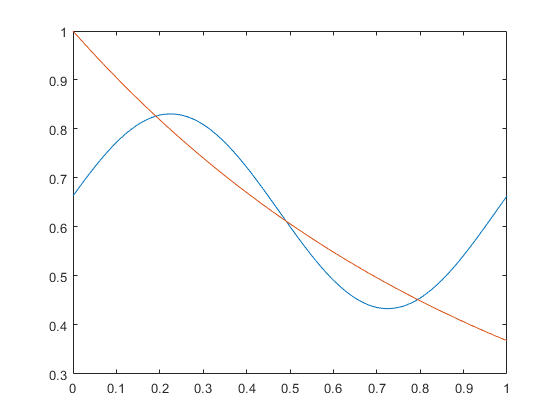

figure(2)

plot(tempo,aux,tempo, g(tempo))


%%% Potencia de yt
py = int(yt^2,t,0,T0);
potY = eval(py)

potY = 0.4193

%%% Porcentagem do sinal
potY*100/valueP

ans = 96.9900